# Activity Recognition Using R(2+1)D Video Classification

This example first shows how to perform activity recognition using a pretrained R(2+1)D [1] convolutional neural network based video classifier and then shows how to use transfer learning to train such a video classifier using video data.

## Overview

Vision-based activity recognition involves predicting the action of an object, such as walking, swimming, or sitting, using a set of video frames. Activity recognition from video has many applications, such as human-computer interaction, robot learning, anomaly detection, surveillance, and object detection. For example, online prediction of multiple actions for incoming videos from multiple cameras can be important for robot learning. Compared to image classification, action recognition using videos is challenging to model because of the inaccurate ground truth data for video data sets, the variety of gestures that actors in a video can perform, the heavily class imbalanced datasets, and the large amount of data required to train a robust classifier from scratch. Deep learning techniques, such as R(2+1)D [1] and SlowFast [2] have shown improved performance on smaller datasets using transfer learning with networks pretrained on large video activity recognition datasets, such as Kinetics-400 [4].

**Note:** This example requires the Computer Vision Toolbox™ Model for R(2+1)D Video Classification. You can install the Computer Vision Toolbox Model for R(2+1)D Video Classification from Add-On Explorer. For more information about installing add-ons, see [Get and Manage Add-Ons](docid:matlab_env#buytlwx).

## Train a Video Classifier for Gesture Recognition

This section of the example shows how the video classifier shown above is trained using transfer learning. Set the `doTraining` variable to `false` to use the pretrained video classifier without having to wait for training to complete. Alternatively, if you want to train the video classifier, set the `doTraining` variable to `true`.

doTraining = true;

### Download Training and Validation Data

% classes = ["fall_floor","fight","hit","normal","run","walk"];
dataFolder = fullfile("G:\FYP\Data_3");

[labels,files] = folders2labels(fullfile(dataFolder,classes),...
    "IncludeSubfolders",true,...
    "FileExtensions",'.avi');

indices = splitlabels(labels,0.8,'randomized');

trainFilenames = files(indices{1});
testFilenames  = files(indices{2});

### Load Dataset

This example uses a datastore to read the videos sequences and the corresponding labels from the video files. 

Specify the number of video frames the datastore should be configured to output for each time data is read from the datastore. 

numFrames = 12;
frameSize = [112,112];
numChannels = 3;

isDataForTraining = true;
dsTrain = createFileDatastore(trainFilenames,numFrames,numChannels,classes,isDataForTraining);

isDataForTraining = false;
dsVal = createFileDatastore(testFilenames,numFrames,numChannels,classes,isDataForTraining);

### Configure R(2+1)D Video Classifier for Transfer Learning

In this example, you create a R(2+1)D video classifier based on the ResNet-3D architecture with 18 Spatio-Temporal residual layers, a 3D Convolution Neural Network Video Classifier pretrained on the Kinetics-400 dataset [4].

Specify ResNet-3D with 18 Spatio-Temporal layers as the base network architecture for the R(2+1)D classifier.

baseNetwork = "resnet-3d-18";

Specify the input size for the R(2+1)D Video Classifier.

inputSize = [frameSize, numChannels, numFrames];

Create a  R(2+1)D Video Classifier by specifying the classes for the HMDB51 dataset and the network input size.

r2plus1d = r2plus1dVideoClassifier(baseNetwork,string(classes),"InputSize",inputSize);

Specify a model name for the video classifier.

r2plus1d.ModelName = "R(2+1)D Activity Recognizer";

### Augment and Preprocess Training Data

Data augmentation provides a way to use limited data sets for training. Augmentation on video data must be the same for a collection of frames based on the network input size. Minor changes, such as translation, cropping, or transforming an image, provide, new, distinct, and unique images that you can use to train a robust video classifier. Datastores are a convenient way to read and augment collections of data. Augment the training video data by using the `augmentVideo` supporting function, defined at the end of this example. 

dsTrain = transform(dsTrain, @augmentVideo);

Preprocess the training video data to resize to the R(2+1)D Video Classifier input size, by using the `preprocessVideoClips`, defined at the end of this example. Specify the `InputNormalizationStatistics` property of the video classifier and input size to the preprocessing function as field values in a struct, `preprocessInfo`. The `InputNormalizationStatistics` property is used to rescale the video frames between 0 and 1, and then normalize the rescaled data using mean and standard deviation. The input size is used to resize the video frames using `imresize` based on the `SizingOption` value in the `info` struct. Alternatively, you could use `"randomcrop"` or `"centercrop"` to random crop or center crop the input data to the input size of the video classifier. Note that data augmentation is not applied to the test and validation data. Ideally, test and validation data should be representative of the original data and is left unmodified for unbiased evaluation.

preprocessInfo.Statistics = r2plus1d.InputNormalizationStatistics;
preprocessInfo.InputSize = inputSize;
preprocessInfo.SizingOption = "resize";
dsTrain = transform(dsTrain, @(data)preprocessVideoClips(data, preprocessInfo));
dsVal = transform(dsVal, @(data)preprocessVideoClips(data, preprocessInfo));

### Define Model Loss Function

The `modelLoss` function, listed at the end of this example, takes as input the R(2+1)D Video Classifier `r2plus1d`, a mini-batch of input data `dlRGB`, and a mini-batch of ground truth label data `dlT`. The function returns the training loss value, the gradients of the loss with respect to the learnable parameters of the classifier, and the mini-batch accuracy of the classifier.

The loss is calculated by computing the cross-entropy loss of the predictions from video classifier. The output predictions of the network are probabilities between 0 and 1 for each of the classes.

        
$$predictions = forward(r2plus1d,dlRGB);$$


        
$$loss = crossentropy(predictions)$$


The accuracy of the classifier is calculated by comparing the classifier `predictions` to the ground truth label of the inputs, `dlT`.

### Specify Training Options

Train with a mini-batch size of 5 for 900 iterations. Specify the iteration after which to save the model with the best validation accuracy by using the `SaveBestAfterIteration` parameter.

Specify the cosine-annealing learning rate schedule [3] parameters:

- A minimum learning rate of 1e-4.

- A maximum learning rate of 1e-3.

- Cosine number of iterations of 200, 300, and 400, after which the learning rate schedule cycle restarts. The option `CosineNumIterations` defines the width of each cosine cycle.

Specify the parameters for SGDM optimization. Initialize the SGDM optimization parameters at the beginning of the training:

- A momentum of 0.9.

- An initial velocity parameter initialized as `[]`.

- An L2 regularization factor of 0.0005.

Specify to dispatch the data in the background using a parallel pool. If `DispatchInBackground` is set to true, open a parallel pool with the specified number of parallel workers, and create a `DispatchInBackgroundDatastore`, provided as part of this example, that dispatches the data in the background to speed up training using asynchronous data loading and preprocessing. By default, this example uses a GPU if one is available. Otherwise, it uses a CPU. Using a GPU requires Parallel Computing Toolbox™ and a CUDA® enabled NVIDIA® GPU. For information about the supported compute capabilities, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f).

params.Classes = classes;
params.MiniBatchSize = 3;
params.NumIterations = 1000;
params.SaveBestAfterIteration = 600;
params.CosineNumIterations = [200, 300, 400];
params.MinLearningRate = 1e-4;
params.MaxLearningRate = 1e-3;
params.Momentum = 0.9;
params.Velocity = [];
params.L2Regularization = 0.0005;
params.ProgressPlot = false;
params.Verbose = true;
params.ValidationData = dsVal;
params.DispatchInBackground = false;
params.NumWorkers = 12;

### Train R(2+1)D Video Classifier

Train the R(2+1)D video classifier using the video data.

For each epoch:

- Shuffle the data before looping over mini-batches of data.

- Use `minibatchqueue` to loop over the mini-batches. The supporting function `createMiniBatchQueue`, listed at the end of this example, uses the given training datastore to create a `minibatchqueue`. 

- Display the loss and accuracy results for each epoch using the supporting function `displayVerboseOutputEveryEpoch`, listed at the end of this example.

For each mini-batch:

- Convert the video data and the labels to `dlarray` objects with the underlying type single.

- To enable processing the time dimension of the the video data using the R(2+1)D Video Classifier specify the temporal sequence dimension, `"T"`. Specify the dimension labels `"SSCTB"` (spatial, spatial, channel, temporal, batch) for the video data, and `"CB"` for the label data.

The `minibatchqueue` object uses the supporting function `batchVideo`, listed at the end of this example, to batch the RGB video data.

params.ModelFilename = "G:\FYP\r2plus1d-OWNdata.mat";
if doTraining
    epoch = 1;
    bestLoss = realmax;
    accTrain = [];
    lossTrain = [];

    iteration = 1;
    start = tic;
    trainTime = start;
    shuffled = shuffleTrainDs(dsTrain);

    % Number of outputs is two: One for RGB frames, and one for ground truth labels.
    numOutputs = 2;
    mbq = createMiniBatchQueue(shuffled, numOutputs, params);
    
    % Use the initializeTrainingProgressPlot and initializeVerboseOutput
    % supporting functions, listed at the end of the example, to initialize
    % the training progress plot and verbose output to display the training
    % loss, training accuracy, and validation accuracy.
    plotters = initializeTrainingProgressPlot(params);
    initializeVerboseOutput(params);

    while iteration <= params.NumIterations

        % Iterate through the data set.
        [dlVideo,dlT] = next(mbq);

        % Evaluate the model loss and gradients using dlfeval.
        [loss,gradients,acc,state] = ...
            dlfeval(@modelLoss,r2plus1d,dlVideo,dlT);

        % Accumulate the loss and accuracies.
        lossTrain = [lossTrain, loss];
        accTrain = [accTrain, acc];

        % Update the network state.
        r2plus1d.State = state;

        % Update the gradients and parameters for the classifier 
        % using the SGDM optimizer.
        [r2plus1d,params.Velocity,learnRate] = ...
            updateLearnables(r2plus1d,gradients,params,params.Velocity,iteration);

        if ~hasdata(mbq) || iteration == params.NumIterations
            % Current epoch is complete. Do validation and update progress.
            trainTime = toc(trainTime);

            [validationTime,cmat,lossValidation,accValidation] = ...
                doValidation(params, r2plus1d);

            accTrain = mean(accTrain);
            lossTrain = mean(lossTrain);

            % Update the training progress.
            displayVerboseOutputEveryEpoch(params,start,learnRate,epoch,iteration,...
                accTrain,accValidation,lossTrain,lossValidation,trainTime,validationTime);
            updateProgressPlot(params,plotters,epoch,iteration,start,lossTrain,accTrain,accValidation);

            % Save the trained video classifier and the parameters, that gave 
            % the best validation loss so far. Use the saveData supporting function,
            % listed at the end of this example.
            bestLoss = saveData(r2plus1d,bestLoss,iteration,cmat,lossTrain,lossValidation,accTrain,accValidation,params);
        end

        if ~hasdata(mbq) && iteration < params.NumIterations
            % Current epoch is complete. Initialize the training loss, accuracy
            % values, and minibatchqueue for the next epoch.
            accTrain = [];
            lossTrain = [];
           
            epoch = epoch + 1;
            trainTime = tic;
            shuffled = shuffleTrainDs(dsTrain);
            mbq = createMiniBatchQueue(shuffled, numOutputs, params);            
        end

        iteration = iteration + 1;
    end

    % Display a message when training is complete.
    endVerboseOutput(params);

    disp("Model saved to: " + params.ModelFilename);
end

 
Training on GPU.
NumIterations:1000
MiniBatchSize:3
Classes:fall_floor,fight,hit,normal,run,walk
|=======================================================================================================================================|
| Epoch | Iteration | Time Elapsed | Mini-Batch | Validation | Mini-Batch | Validation |  Base Learning  | Train Time | Validation Time |
|       |           |  (hh:mm:ss)  |  Accuracy  |  Accuracy  |    Loss    |    Loss    |      Rate       | (hh:mm:ss) |   (hh:mm:ss)    |
|=======================================================================================================================================|


|   1   |    296    |   00:09:19   |   49.21%   |   53.30%   |   1.3984   |   1.4127   | 0.0007911220577 |  00:07:32  |    00:01:47     |
|   2   |    592    |   00:16:22   |   62.05%   |   62.47%   |   1.0491   |   1.1970   | 0.0008875499813 |  00:05:20  |    00:01:42     |
|   3   |    888    |   00:23:20   |   66.89%   |   69.37%   |   0.9305   |   0.8951   | 0.0001019971159 |  00:05:16  |    00:01:41     |
|   4   |   1000    |   00:27:08   |   63.99%   |   69.14%   |   0.9818   |   1.0526   | 0.0001000000000 |  00:02:02  |    00:01:41     |


|=======================================================================================================================================|


Model saved to: G:\FYP\r2plus1d-OWNdata.mat


## Evaluate Trained Video Classifier

Use the test data set to evaluate the accuracy of the trained video classifier. 

Load the best model saved during training or use the pretrained model.

if doTraining
    transferLearned = load(params.ModelFilename);
    r2plus1dPretrained = transferLearned.data.r2plus1d;
end

Create a `minibatchqueue` object to load batches of the test data.

numOutputs = 2;
mbq = createMiniBatchQueue(dsVal, numOutputs, params);

For each batch of evaluation data, make predictions using the R(2+1)D Video Classifier, and compute the prediction accuracy using a confusion matrix.

numClasses = numel(params.Classes);
cmat = sparse(numClasses,numClasses);

while hasdata(mbq)
    [dlVideo,dlT] = next(mbq);

    % Computer the predictions of the trained R(2+1)D
    % Video Classifier.
    dlYPred = predict(r2plus1dPretrained,dlVideo);
    dlYPred = squeezeIfNeeded(dlYPred, dlT);

    % Aggregate the confusion matrix by using the maximum
    % values of the prediction scores and the ground truth labels.
    [~,TTest] = max(dlT,[],1);
    [~,YPred] = max(dlYPred,[],1);
    cmat = aggregateConfusionMetric(cmat,TTest,YPred);
end

Compute the average clip classification accuracy for the trained R(2+1)D Video Classifier.

evalClipAccuracy = sum(diag(cmat))./sum(cmat,"all")

evalClipAccuracy = 0.6937

Display the confusion matrix.

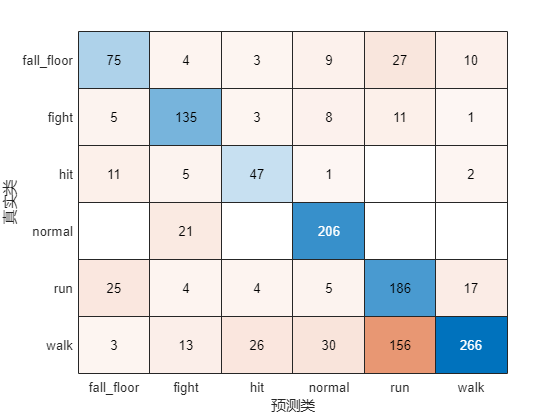

figure
chart = confusionchart(cmat,classes);

The R(2+1)D video classifier that is pretrained on the Kinetics-400 dataset, provides strong performance for human activity recognition on transfer learning. The above training was run on 24GB Titan-X GPU for about 30 minutes. When training from scratch on a small activity recognition video dataset, the training time and convergence takes much longer than the pretrained video classifier. Transer learning using the Kinetics-400 pretrained R(2+1)D video classifier also avoids overfitting the classifier when ran for larger number of epochs. To learn more about video recognition using deep learning, see [Getting Started with Video Classification Using Deep Learning](docid:vision_ug#mw_0931e976-7a95-4b0d-8fa5-be50fd9f8fbe).

## Supporting Functions

#### `createFileDatastore`

The `createFileDatastore` function creates a `FileDatastore` object using the given folder name. The `FileDatastore` object reads the data in `'partialfile'` mode, so every read can return partially read frames from videos. This feature helps with reading large video files, if all of the frames do not fit in memory.

function datastore = createFileDatastore(trainingFolder,numFrames,numChannels,classes,isDataForTraining)
    readFcn = @(f,u)readVideo(f,u,numFrames,numChannels,classes,isDataForTraining);
    datastore = fileDatastore(trainingFolder,...
        'IncludeSubfolders',true,...
        'FileExtensions','.avi',...
        'ReadFcn',readFcn,...
        'ReadMode','partialfile');
end

#### `shuffleTrainDs`

The `shuffleTrainDs` function shuffles the files present in the training datastore, `dsTrain`.


function shuffled = shuffleTrainDs(dsTrain)
shuffled = copy(dsTrain);
transformed = isa(shuffled, 'matlab.io.datastore.TransformedDatastore');
if transformed
    files = shuffled.UnderlyingDatastores{1}.Files;
else 
    files = shuffled.Files;
end
n = numel(files);
shuffledIndices = randperm(n);  
if transformed
    shuffled.UnderlyingDatastores{1}.Files = files(shuffledIndices);
else
    shuffled.Files = files(shuffledIndices);
end

reset(shuffled);

end

#### `readVideo`

The `readVideo` function reads video frames, and the corresponding label values for a given video file. During training, the read function reads the specific number of frames as per the network input size, with a randomly chosen starting frame. During testing, all the frames are sequentially read. The video frames are resized to the required classifier network input size for training, and for testing and validation.

function [data,userdata,done] = readVideo(filename,userdata,numFrames,numChannels,classes,isDataForTraining)
    if isempty(userdata)
        userdata.reader      = VideoReader(filename);
        userdata.batchesRead = 0;
        
        userdata.label = getLabel(filename,classes);

        totalFrames = floor(userdata.reader.Duration * userdata.reader.FrameRate);
        totalFrames = min(totalFrames, userdata.reader.NumFrames);
        userdata.totalFrames = totalFrames;
        userdata.datatype = class(read(userdata.reader,1));
    end
    reader      = userdata.reader;
    totalFrames = userdata.totalFrames;
    label       = userdata.label;
    batchesRead = userdata.batchesRead;

    if isDataForTraining
        video = readForTraining(reader, numFrames, totalFrames);
    else
        video = readForValidation(reader, userdata.datatype, numChannels, numFrames, totalFrames);
    end   

    data = {video, label};

    batchesRead = batchesRead + 1;

    userdata.batchesRead = batchesRead;

    if numFrames > totalFrames
        numBatches = 1;
    else
        numBatches = floor(totalFrames/numFrames);
    end
    % Set the done flag to true, if the reader has read all the frames or
    % if it is training.
    done = batchesRead == numBatches || isDataForTraining;
end

#### `readForTraining`

The `readForTraining` function reads the video frames for training the video classifier. The function reads the specific number of frames as per the network input size, with a randomly chosen starting frame. If there are not enough frames left over, the video sequence is repeated to pad the required number of frames.

function video = readForTraining(reader, numFrames, totalFrames)
    if numFrames >= totalFrames
        startIdx = 1;
        endIdx = totalFrames;
    else
        startIdx = randperm(totalFrames - numFrames + 1);
        startIdx = startIdx(1);
        endIdx = startIdx + numFrames - 1;
    end
    video = read(reader,[startIdx,endIdx]);
    if numFrames > totalFrames
        % Add more frames to fill in the network input size.
        additional = ceil(numFrames/totalFrames);
        video = repmat(video,1,1,1,additional);
        video = video(:,:,:,1:numFrames);
    end
end

#### `readForValidation`

The `readForValidation` function reads the video frames for evaluating the trained video classifier. The function reads the specific number of frames sequentially as per the network input size. If there are not enough frames left over, the video sequence is repeated to pad the required number of frames.

function video = readForValidation(reader, datatype, numChannels, numFrames, totalFrames)
    H = reader.Height;
    W = reader.Width;
    toRead = min([numFrames,totalFrames]);
    video = zeros([H,W,numChannels,toRead], datatype);
    frameIndex = 0;
    while hasFrame(reader) && frameIndex < numFrames
        frame = readFrame(reader);
        frameIndex = frameIndex + 1;
        video(:,:,:,frameIndex) = frame;
    end
    
    if frameIndex < numFrames
        video = video(:,:,:,1:frameIndex);    
        additional = ceil(numFrames/frameIndex);
        video = repmat(video,1,1,1,additional);
        video = video(:,:,:,1:numFrames);       
    end
end

#### `getLabel`

The `getLabel` function obtains the label name from the full path of a filename. The label for a file is the folder in which it exists. For example, for a file path such as `"/path/to/dataset/clapping/video_0001.avi"`, the label name is `"clapping"`.

function label = getLabel(filename,classes)
    folder = fileparts(string(filename));
    [~,label] = fileparts(folder);
    label = categorical(string(label), string(classes));
end

#### `augmentVideo`

The `augmentVideo` function augments the video frames for training the video classifier. The function augments a video sequence with the same augmentation technique provided by the `augmentTransform` function.

function data = augmentVideo(data)
    numClips = size(data,1);
    for ii = 1:numClips
        video = data{ii,1};
        % HxWxC
        sz = size(video,[1,2,3]);
        % One augment fcn per clip
        augmentFcn = augmentTransform(sz);
        data{ii,1} = augmentFcn(video);
    end
end

#### `augmentTransform`

The `augmentTransform` function creates an augmentation method with random left-right flipping and scaling factors.

function augmentFcn = augmentTransform(sz)
% Randomly flip and scale the image.
tform = randomAffine2d('XReflection',true,'Scale',[1 1.1]);
rout = affineOutputView(sz,tform,'BoundsStyle','CenterOutput');

augmentFcn = @(data)augmentData(data,tform,rout);

    function data = augmentData(data,tform,rout)
        data = imwarp(data,tform,'OutputView',rout);
    end
end

#### `preprocessVideoClips`

The `preprocessVideoClips` function preprocesses the training video data to resize to the R(2+1)D Video Classifier input size. It takes the `InputNormalizationStatistics` and the `InputSize` properties of the video classifier in a struct, `info`. The `InputNormalizationStatistics` property is used to rescale the video frames between 0 and 1, and then normalize the rescaled data using mean and standard deviation. The input size is used to resize the video frames using `imresize` based on the `SizingOption` value in the `info` struct. Alternatively, you could use `"randomcrop"` or `"centercrop"` as values for `SizingOption` to random crop or center crop the input data to the input size of the video classifier.

function data = preprocessVideoClips(data, info)
    inputSize = info.InputSize(1:2);
    sizingOption = info.SizingOption;
    switch sizingOption
        case "resize"
            sizingFcn = @(x)imresize(x,inputSize);
        case "randomcrop"
            sizingFcn = @(x)cropVideo(x,@randomCropWindow2d,inputSize);
        case "centercrop"
            sizingFcn = @(x)cropVideo(x,@centerCropWindow2d,inputSize);
    end
    numClips = size(data,1);

    minValue = info.Statistics.Min;
    maxValue = info.Statistics.Max;
    minValue = reshape(minValue, 1, 1, 3);
    maxValue = reshape(maxValue, 1, 1, 3);

    meanValue = info.Statistics.Mean;
    stdValue  = info.Statistics.StandardDeviation;
    meanValue = reshape(meanValue, 1, 1, 3);
    stdValue  = reshape(stdValue, 1, 1, 3);

    for ii = 1:numClips
        video = data{ii,1};
        resized = sizingFcn(video);

        % Cast the input to single.
        resized = single(resized);

        % Rescale the input between 0 and 1.
        resized = rescale(resized,0,1,"InputMin",minValue,"InputMax",maxValue);

        % Normalize using mean and standard deviation.
        resized = resized - meanValue;
        resized = resized ./ stdValue;
        data{ii,1} = resized;
    end

    function outData = cropVideo(data, cropFcn, inputSize)
        imsz = size(data,[1,2]);
        cropWindow = cropFcn(imsz, inputSize);
        numBatches = size(data,4);
        sz = [inputSize, size(data,3), numBatches];
        outData = zeros(sz, 'like', data);
        for b = 1:numBatches
            outData(:,:,:,b) = imcrop(data(:,:,:,b), cropWindow);
        end
    end
end

#### `createMiniBatchQueue`

The `createMiniBatchQueue` function creates a `minibatchqueue` object that provides `miniBatchSize` amount of data from the given datastore. It also creates a `DispatchInBackgroundDatastore` if a parallel pool is open.


function mbq = createMiniBatchQueue(datastore, numOutputs, params)
if params.DispatchInBackground && isempty(gcp('nocreate'))
    % Start a parallel pool, if DispatchInBackground is true, to dispatch
    % data in the background using the parallel pool.
    c = parcluster('local');
    c.NumWorkers = params.NumWorkers;
    parpool('local',params.NumWorkers);
end
p = gcp('nocreate');
if ~isempty(p)
    datastore = DispatchInBackgroundDatastore(datastore, p.NumWorkers);
end

inputFormat(1:numOutputs-1) = "SSCTB";
outputFormat = "CB";
mbq = minibatchqueue(datastore, numOutputs, ...
    "MiniBatchSize", params.MiniBatchSize, ...
    "MiniBatchFcn", @batchVideo, ...
    "MiniBatchFormat", [inputFormat,outputFormat]);
end

#### `batchVideo`

The `batchVideo` function batches the video, and the label data from cell arrays. It uses `onehotencode` function to encode ground truth categorical labels into one-hot arrays. The one-hot encoded array contains a `1` in the position corresponding to the class of the label, and `0` in every other position.

function [video,labels] = batchVideo(video, labels)
% Batch dimension: 5
video = cat(5,video{:});

% Batch dimension: 2
labels = cat(2,labels{:});

% Feature dimension: 1
labels = onehotencode(labels,1);
end

#### `modelLoss`

The `modelLoss` function takes as input a mini-batch of RGB data `dlRGB`, and the corresponding target `dlT`, and returns the corresponding loss, the gradients of the loss with respect to the learnable parameters, and the training accuracy. To compute the gradients, evaluate the `modelLoss` function using the `dlfeval` function in the training loop.

function [loss,gradientsRGB,acc,stateRGB] = modelLoss(r2plus1d,dlRGB,dlT)
[dlYPredRGB,stateRGB] = forward(r2plus1d,dlRGB);
dlYPred = squeezeIfNeeded(dlYPredRGB, dlT);

loss = crossentropy(dlYPred,dlT);

gradientsRGB = dlgradient(loss,r2plus1d.Learnables);

% Calculate the accuracy of the predictions.
[~,TTest] = max(dlT,[],1);
[~,YPred] = max(dlYPred,[],1);

acc = gather(extractdata(sum(TTest == YPred)./numel(TTest)));    
end

#### `squeezeIfNeeded`

function dlYPred = squeezeIfNeeded(dlYPred, T)
if ~isequal(size(T), size(dlYPred))
    dlYPred = squeeze(dlYPred);
    dlYPred = dlarray(dlYPred,dims(T));
end
end

#### `updateLearnables`

The `updateLearnables` function updates the provided `dlnetwork` object with gradients and other parameters using SGDM optimization function `sgdmupdate`.

function [r2plus1d,velocity,learnRate] = updateLearnables(r2plus1d,gradients,params,velocity,iteration)
    % Determine the learning rate using the cosine-annealing learning rate schedule.
    learnRate = cosineAnnealingLearnRate(iteration, params);

    % Apply L2 regularization to the weights.
    learnables = r2plus1d.Learnables;
    idx = learnables.Parameter == "Weights";
    gradients(idx,:) = dlupdate(@(g,w) g + params.L2Regularization*w, gradients(idx,:), learnables(idx,:));

    % Update the network parameters using the SGDM optimizer.
    [r2plus1d, velocity] = sgdmupdate(r2plus1d, gradients, velocity, learnRate, params.Momentum);
end


#### `cosineAnnealingLearnRate`

The `cosineAnnealingLearnRate` function computes the learning rate based on the current iteration number, minimum learning rate, maximum learning rate, and number of iterations for annealing [3].

function lr = cosineAnnealingLearnRate(iteration, params)
    if iteration == params.NumIterations
        lr = params.MinLearningRate;
        return;
    end
    cosineNumIter = [0, params.CosineNumIterations];
    csum = cumsum(cosineNumIter);
    block = find(csum >= iteration, 1,'first');
    cosineIter = iteration - csum(block - 1);
    annealingIteration = mod(cosineIter, cosineNumIter(block));
    cosineIteration = cosineNumIter(block);
    minR = params.MinLearningRate;
    maxR = params.MaxLearningRate;
    cosMult = 1 + cos(pi * annealingIteration / cosineIteration);
    lr = minR + ((maxR - minR) *  cosMult / 2);
end

#### `aggregateConfusionMetric`

The `aggregateConfusionMetric` function incrementally fills a confusion matrix based on the predicted results `YPred` and the expected results `TTest`.

function cmat = aggregateConfusionMetric(cmat,TTest,YPred)
TTest = gather(extractdata(TTest));
YPred = gather(extractdata(YPred));
[m,n] = size(cmat);
cmat = cmat + full(sparse(TTest,YPred,1,m,n));
end

#### `doValidation`

The `doValidation` function validates the video classifier using the validation data.

function [validationTime, cmat, lossValidation, accValidation] = doValidation(params, r2plus1d)

    validationTime = tic;

    numOutputs = 2;
    mbq = createMiniBatchQueue(params.ValidationData, numOutputs, params);

    lossValidation = [];
    numClasses = numel(params.Classes);
    cmat = sparse(numClasses,numClasses);
    while hasdata(mbq)

        [dlVideo,T] = next(mbq);

        % Pass the video input through the R(2+1)D Video Classifier.
        dlT = predict(r2plus1d,dlVideo);
        dlT = squeezeIfNeeded(dlT, T);

        % Calculate the cross-entropy loss.
        loss = crossentropy(dlT,T);

        % Calculate the accuracy of the predictions.
        [~,TTest] = max(T,[],1);
        [~,YPred] = max(dlT,[],1);

        lossValidation = [lossValidation,loss];
        cmat = aggregateConfusionMetric(cmat,TTest,YPred);
    end
    lossValidation = mean(lossValidation);
    accValidation = sum(diag(cmat))./sum(cmat,"all");

    validationTime = toc(validationTime);
end

#### `saveData`

The `saveData` function saves the given R(2+1)D Video Classifier, accuracy, loss, and other training parameters to a MAT-file.

function bestLoss = saveData(r2plus1d,bestLoss,iteration,cmat,lossTrain,lossValidation,accTrain,accValidation,params)
if iteration >= params.SaveBestAfterIteration
    lossValidtion = extractdata(gather(lossValidation));
    if lossValidtion < bestLoss
        params = rmfield(params, 'Velocity');
        bestLoss = lossValidtion;
        r2plus1d = gatherFromGPUToSave(r2plus1d);
        data.BestLoss = bestLoss;
        data.TrainingLoss = extractdata(gather(lossTrain));
        data.TrainingAccuracy = accTrain;
        data.ValidationAccuracy = accValidation;
        data.ValidationConfmat= cmat;
        data.r2plus1d = r2plus1d;
        data.Params = params;
        save(params.ModelFilename, 'data');
    end
end
end

#### `gatherFromGPUToSave`

The `gatherFromGPUToSave` function gathers data from the GPU in order to save the video classifier to disk.

function r2plus1d = gatherFromGPUToSave(r2plus1d)
if ~canUseGPU
    return;
end
r2plus1d.Learnables = gatherValues(r2plus1d.Learnables);
r2plus1d.State = gatherValues(r2plus1d.State);
    function tbl = gatherValues(tbl)
        for ii = 1:height(tbl)
            tbl.Value{ii} = gather(tbl.Value{ii});
        end
    end
end

#### `checkForHMDB51Folder`

The `checkForHMDB51Folder` function checks for the downloaded data in the download folder.

function classes = checkForHMDB51Folder(dataLoc)
hmdbFolder = fullfile(dataLoc, "hmdb51_org");
if ~isfolder(hmdbFolder)
    error("Download 'hmdb51_org.rar' file using the supporting function 'downloadHMDB51' before running the example and extract the RAR file.");    
end

classes = ["brush_hair","cartwheel","catch","chew","clap","climb","climb_stairs",...
    "dive","draw_sword","dribble","drink","eat","fall_floor","fencing",...
    "flic_flac","golf","handstand","hit","hug","jump","kick","kick_ball",...
    "kiss","laugh","pick","pour","pullup","punch","push","pushup","ride_bike",...
    "ride_horse","run","shake_hands","shoot_ball","shoot_bow","shoot_gun",...
    "sit","situp","smile","smoke","somersault","stand","swing_baseball","sword",...
    "sword_exercise","talk","throw","turn","walk","wave"];
expectFolders = fullfile(hmdbFolder, classes);
if ~all(arrayfun(@(x)exist(x,'dir'),expectFolders))
    error("Download hmdb51_org.rar using the supporting function 'downloadHMDB51' before running the example and extract the RAR file.");
end
end

#### `initializeTrainingProgressPlot`

The `initializeTrainingProgressPlot` function configures two plots for displaying the training loss, training accuracy, and validation accuracy.

function plotters = initializeTrainingProgressPlot(params)
if params.ProgressPlot
    % Plot the loss, training accuracy, and validation accuracy.
    figure
    
    % Loss plot
    subplot(2,1,1)
    plotters.LossPlotter = animatedline;
    xlabel("Iteration")
    ylabel("Loss")
    
    % Accuracy plot
    subplot(2,1,2)
    plotters.TrainAccPlotter = animatedline('Color','b');
    plotters.ValAccPlotter = animatedline('Color','g');
    legend('Training Accuracy','Validation Accuracy','Location','northwest');
    xlabel("Iteration")
    ylabel("Accuracy")
else
    plotters = [];
end
end

#### `updateProgressPlot`

The `updateProgressPlot` function updates the progress plot with loss and accuracy information during training.

function updateProgressPlot(params,plotters,epoch,iteration,start,lossTrain,accuracyTrain,accuracyValidation)
if params.ProgressPlot
    
    % Update the training progress.
    D = duration(0,0,toc(start),"Format","hh:mm:ss");
    title(plotters.LossPlotter.Parent,"Epoch: " + epoch + ", Elapsed: " + string(D));
    addpoints(plotters.LossPlotter,iteration,double(gather(extractdata(lossTrain))));
    addpoints(plotters.TrainAccPlotter,iteration,accuracyTrain);
    addpoints(plotters.ValAccPlotter,iteration,accuracyValidation);
    drawnow
end
end

#### `initializeVerboseOutput`

function initializeVerboseOutput(params)
if params.Verbose
    disp(" ")
    if canUseGPU
        disp("Training on GPU.")
    else
        disp("Training on CPU.")
    end
    p = gcp('nocreate');
    if ~isempty(p)
        disp("Training on parallel cluster '" + p.Cluster.Profile + "'. ")
    end
    disp("NumIterations:" + string(params.NumIterations));
    disp("MiniBatchSize:" + string(params.MiniBatchSize));
    disp("Classes:" + join(string(params.Classes), ","));
    disp("|=======================================================================================================================================|")
    disp("| Epoch | Iteration | Time Elapsed | Mini-Batch | Validation | Mini-Batch | Validation |  Base Learning  | Train Time | Validation Time |")
    disp("|       |           |  (hh:mm:ss)  |  Accuracy  |  Accuracy  |    Loss    |    Loss    |      Rate       | (hh:mm:ss) |   (hh:mm:ss)    |")
    disp("|=======================================================================================================================================|")
end
end

#### `displayVerboseOutputEveryEpoch`

function displayVerboseOutputEveryEpoch(params,start,learnRate,epoch,iteration,...
        accTrain,accValidation,lossTrain,lossValidation,trainTime,validationTime)
    if params.Verbose
        D = duration(0,0,toc(start),'Format','hh:mm:ss');
        trainTime = duration(0,0,trainTime,'Format','hh:mm:ss');
        validationTime = duration(0,0,validationTime,'Format','hh:mm:ss');

        lossValidation = gather(extractdata(lossValidation));
        lossValidation = compose('%.4f',lossValidation);

        accValidation = composePadAccuracy(accValidation);

        lossTrain = gather(extractdata(lossTrain));
        lossTrain = compose('%.4f',lossTrain);

        accTrain = composePadAccuracy(accTrain);
        learnRate = compose('%.13f',learnRate);

        disp("| " + ...
            pad(string(epoch),5,'both') + " | " + ...
            pad(string(iteration),9,'both') + " | " + ...
            pad(string(D),12,'both') + " | " + ...
            pad(string(accTrain),10,'both') + " | " + ...
            pad(string(accValidation),10,'both') + " | " + ...
            pad(string(lossTrain),10,'both') + " | " + ...
            pad(string(lossValidation),10,'both') + " | " + ...
            pad(string(learnRate),13,'both') + " | " + ...
            pad(string(trainTime),10,'both') + " | " + ...
            pad(string(validationTime),15,'both') + " |")
    end
    function acc = composePadAccuracy(acc)
        acc = compose('%.2f',acc*100) + "%";
        acc = pad(string(acc),6,'left');
    end
end

#### `endVerboseOutput`

The `endVerboseOutput` function displays the end of verbose output during training.

function endVerboseOutput(params)
if params.Verbose
    disp("|=======================================================================================================================================|")
end
end


## References

[1] Du Tran, Heng Wang, Lorenzo Torresani, Jamie Ray, Yann LeCun, Manohar Paluri. "A Closer Look at Spatiotemporal Convolutions for Action Recognition". Proceedings of the IEEE Conference on Computer Vision and Pattern Recognition (CVPR), 2018, pp. 6450-6459.

[2] Christoph Feichtenhofer, Haoqi Fan, Jitendra Malik, and Kaiming He. "SlowFast Networks for Video Recognition." *Proceedings of the IEEE Conference on Computer Vision and Pattern Recognition* (CVPR), 2019.

[3] Loshchilov, Ilya, and Frank Hutter. "SGDR: Stochastic Gradient Descent with Warm Restarts." *International Conferencee on Learning Representations 2017*. Toulon, France: ICLR, 2017.

[4] Will Kay, Joao Carreira, Karen Simonyan, Brian Zhang, Chloe Hillier, Sudheendra Vijayanarasimhan, Fabio Viola, Tim Green, Trevor Back, Paul Natsev, Mustafa Suleyman, Andrew Zisserman. "The Kinetics Human Action Video Dataset." *arXiv preprint arXiv:1705.06950*, 2017.

*Copyright 2021 The MathWorks, Inc.*